clc
clear
close all

% 参数定义
FIRNUMBER = 25;          % 滤波器系数数量
SAMPLEF = 10000;         % 采样频率
SIGNAL1F = 1000;         % 信号1频率
SIGNAL2F = 4500;         % 信号2频率
PI = 3.1415926;
f2PI = 2 * PI;

% 滤波器系数
fHn = [0.0, 0.0, 0.001, -0.002, -0.002, 0.01, -0.009, ...
       -0.018, 0.049, -0.02, -0.11, 0.28, 0.64, 0.28, ...
       -0.11, -0.02, 0.049, -0.018, -0.009, 0.01, ...
       -0.002, -0.002, 0.001, 0.0, 0.0];

% 初始变量
fXn = zeros(1, FIRNUMBER);  % 输入存储
fSignal1 = 0.0;            % 信号1初始相位
fSignal2 = PI * 0.1;       % 信号2初始相位
fStepSignal1 = 2 * PI / 30; % 信号1步进
fStepSignal2 = 2 * PI * 1.4; % 信号2步进
nIn = 0; nOut = 0;

% 数据存储
num_samples = 256;        % 模拟输入/输出存储数量
fIn = zeros(1, num_samples);
fOut = zeros(1, num_samples);

% 循环计算
for n = 1:1000 % 模拟运行 1000 个采样点
    % 生成输入波形
    fXn = [sin(fSignal1) + cos(fSignal2) / 6.0, fXn(1:end-1)];
    fSignal1 = fSignal1 + fStepSignal1;
    if fSignal1 >= f2PI
        fSignal1 = fSignal1 - f2PI;
    end
    fSignal2 = fSignal2 + fStepSignal2;
    if fSignal2 >= f2PI
        fSignal2 = fSignal2 - f2PI;
    end
    
    % 保存输入数据
    fIn(nIn + 1) = fXn(1);
    nIn = mod(nIn + 1, num_samples);
    
    % FIR 滤波
    fSum = sum(fXn .* fHn);
    fOut(nOut + 1) = fSum;
    nOut = mod(nOut + 1, num_samples);
end

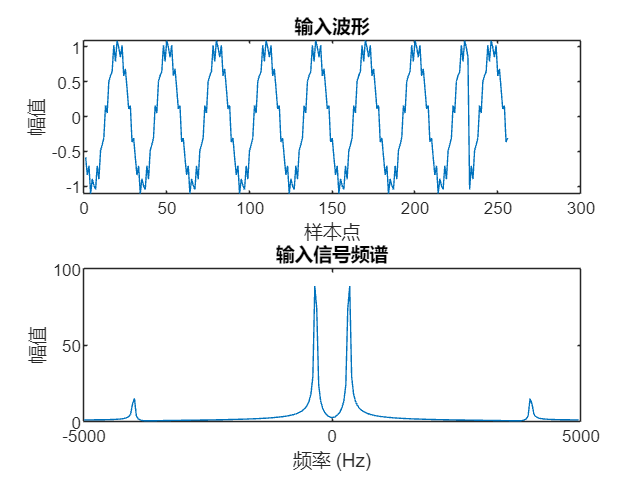

% 计算频谱
frequencies = (-num_samples/2:num_samples/2-1) * (SAMPLEF / num_samples); % 频率轴（中心化）
fIn_fft = fftshift(abs(fft(fIn)));   % 中心化输入频谱幅值
fOut_fft = fftshift(abs(fft(fOut))); % 中心化输出频谱幅值

% 绘制输入和输出波形
figure;
subplot(2,1,1);
plot(fIn);
title('输入波形');
xlabel('样本点');
ylabel('幅值');

subplot(2,1,2)
plot(frequencies, fIn_fft);
title('输入信号频谱');
xlabel('频率 (Hz)');
ylabel('幅值');

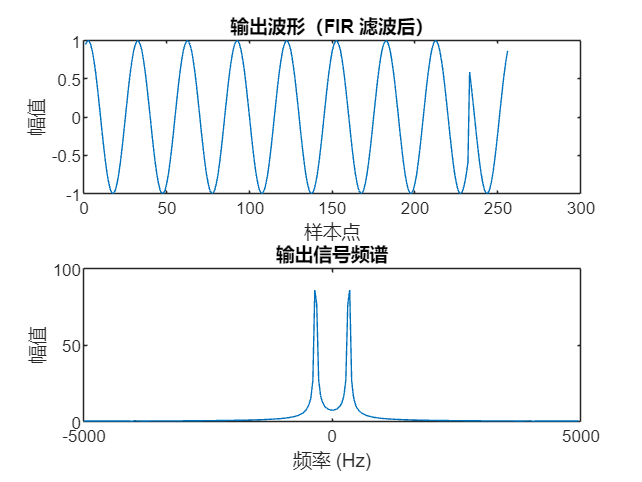


figure
subplot(2,1,1);
plot(fOut);
title('输出波形（FIR 滤波后）');
xlabel('样本点');
ylabel('幅值');

subplot(2,1,2);
plot(frequencies, fOut_fft);
title('输出信号频谱');
xlabel('频率 (Hz)');
ylabel('幅值');